# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 4.5.1 Polar Format Algorithm - Point Targets

% Speed of light
c = 299792458;

% Set the range to the image center
range_center = 1000; % meters

% Set the target locations and RCS
x_target = [-10, 5, -8, 8]; % meters
y_target = [10, -3, -8, 12]; % meters
z_target = [5, 0, -5, 11];
rcs = [10, 10, 7, 5]; % m^2

% Set the image span
x_span = 30; % meters
y_span = 30; % meters
z_span = 30; %meters

% Set the number of bins in the image
nx = 400; % Number of bins in x-direction
ny = 400; % Number of bins in y-direction
nz = 400; % Number of bins in z-direction

% Set the start frequency and bandwidth
start_frequency = 5e9; % Staring frequency (Hz)
bandwidth = 100e6; % Operating bandwidth (Hz)

% Set the azimuth span for the synthetic aperture
az_start = 5; % degrees
az_end = 5.5; % degrees

% Set the elevation span for the synthetic aperture
el_start = -0.5;
el_end = 0.5;

% Set the window type for the image
window_type = 'None';

% Set the dynamic range for the image
dynamic_range = 30; % dB

% Set up the azimuth space
r = sqrt(x_span ^ 2 + y_span ^ 2);
da = c / (2.0 * r * start_frequency);
na = round(deg2rad(az_end - az_start) / da); 
az = linspace(az_start, az_end, na);
az = az - mean(az);

% Set up the elevation space
r = sqrt(x_span ^ 2 + z_span ^ 2);
de = c / (2.0 * r * start_frequency);
ne = round(deg2rad(el_end - el_start) / de); 
el = linspace(el_start, el_end, ne);
el = el - mean(el);

% Set up the frequency space
df = c / (2.0 * r);
nf = floor(bandwidth / df);
frequency = linspace(start_frequency, start_frequency + bandwidth, nf);

% Shorthand and helps with computational load
ca = cosd(az);
sa = sind(az);

ce = cosd(el);
se = sind(el);

% Calculate the signal in wavenumber space
signal = zeros(nf, na, ne);
kx = zeros(nf, na, ne);
ky = zeros(nf, na, ne);
kz = zeros(nf, na, ne);

kc = 2 * pi * frequency / c;

for ia = 1:na
    for ie = 1:ne
        r_los = [ca(ia) * ce(ie), sa(ia) * ce(ie), se(ie)];
        kx(:,ia,ie) = kc .* ca(ia) .* ce(ie);
        ky(:,ia,ie) = kc .* sa(ia) .* ce(ie);
        kz(:,ia,ie) = kc .* se(ie);
        for it = 1:length(x_target)
            r_target = dot(r_los, [x_target(it), y_target(it), z_target(it)]);
            signal(:,ia,ie) = signal(:,ia,ie) + rcs(it) * exp(1j * 2.0 * kc * r_target)';
        end
    end
end

% Set up the 3D wavenumber space for reformatting
kxmin = min(min(min(kx)));  kxmax = max(max(max(kx)));
kymin = min(min(min(ky)));  kymax = max(max(max(ky)));
kzmin = min(min(min(kz)));  kzmax = max(max(max(kz)));

kxp = linspace(kxmin, kxmax);
kyp = linspace(kymin, kymax);
kzp = linspace(kzmin, kzmax);

[kxp, kyp, kzp] = meshgrid(kxp, kyp, kzp);

% Set up the interpolations
F = scatteredInterpolant(kx(:), ky(:), kz(:), signal(:));

clear kx ky kz

% Perform the interpolation
new_signal = F(kxp, kyp, kzp);

% Get the frequency step size
frequency_step = c / (2 * pi) * (kxp(1,2,1) - kxp(1,1,1));

% Calculate the maximum scene size and resolution
range_extent = c / (2 * frequency_step);

% Calculate the range window for the pulses
range_window = linspace(-0.5 * range_extent, 0.5 * range_extent, nx);
del_r = range_window(2) - range_window(1);
range_window = range_window - del_r/2;

% Get the frequency step size
frequency_step = c / (2 * pi) * (kyp(2,1,1) - kyp(1,1,1));

% Calculate the maximum scene size and resolution
cross_range_extent_az = c / (2 * frequency_step);

% Calculate the range window for the pulses
cross_range_window_az = linspace(-0.5 * cross_range_extent_az, 0.5 * cross_range_extent_az, ny);
del_az = cross_range_window_az(2) - cross_range_window_az(1);
cross_range_window_az = cross_range_window_az - del_az/2;

% Get the frequency step size
frequency_step = c / (2 * pi) * (kzp(1,1,2) - kzp(1,1,1));

% Calculate the maximum scene size and resolution
cross_range_extent_el = c / (2 * frequency_step);

% Calculate the range window for the pulses
cross_range_window_el = linspace(-0.5 * cross_range_extent_el, 0.5 * cross_range_extent_el, nz);
del_el = cross_range_window_el(2) - cross_range_window_el(1);
cross_range_window_el = cross_range_window_el - del_az/2;

% Calculate the signal in range, azimuth, and elevation
rae_signal = fftshift(ifftn(new_signal, [nx, ny, nz]));


#### Plot the focused image

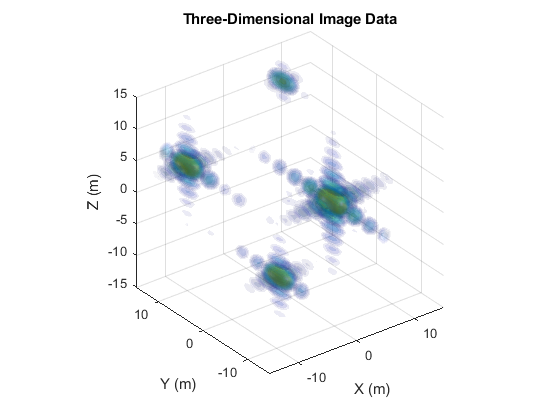

plot_iso(range_window,cross_range_window_az,cross_range_window_el,abs(rae_signal) / max(max(max(abs(rae_signal)))),15)

xlim([-0.5 * x_span, 0.5 * x_span])
ylim([-0.5 * y_span, 0.5 * y_span])
zlim([-0.5 * z_span, 0.5 * z_span])

% Set the title and labels
title('Three-Dimensional Image Data')
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');